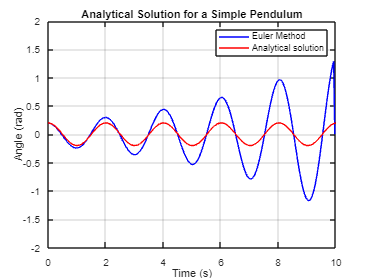

% Constants
g = 9.81;  % acceleration due to gravity (m/s^2)
length = 1; % length of the pendulum (m)
time_step = 0.04; % time step (s)
total_time = 10;  % total simulation time (s)
num_steps = total_time / time_step; % number of time steps

theta0 = 0.2; % initial angle (rad)
phi = 0; % phase constant

% Initial conditions
theta = 0.2;  % initial angle (rad)
omega = 0.0;  % initial angular velocity (rad/s)

% Preallocate arrays for efficiency
theta_values = zeros(1, num_steps);
omega_values = zeros(1, num_steps);
time_values = 0:time_step:(total_time - time_step); % time array

time_values_analytical = 0:time_step:total_time; % time array for analytical

% Simulation using Euler's method
% for i = 1:num_steps
%     % Store the current values
%     theta_values(i) = theta;
%     
%     % Calculate the new values using Euler's method
%     alpha = -(g / length) * sin(theta);  % angular acceleration (rad/s^2)
%     theta = theta + omega * time_step;   % update angle using old omega
%     omega = omega + alpha * time_step;   % update angular velocity
%     
% end
for i = 1:num_steps-1
    % Update angular velocity
    omega_new = omega - (g / length) * theta * time_step;
    % Update angle
    theta_new = theta + omega * time_step; % Note the use of omega, not omega_new
    
    % Store new values
    omega = omega_new;
    theta = theta_new;
    
    theta_values(i) = theta;
    omega_values(i) = omega;
end    

% The analytical solution
% Natural frequency of the pendulum
omega_natural = sqrt(g / length); 

% Analytical solution for theta as a function of time
theta_analytical = theta0 * cos(omega_natural * time_values_analytical + phi);

% Plotting
figure;
plot(time_values, theta_values, 'b-','DisplayName', 'Euler Method');
xlabel('Time (s)');
ylabel('Angle (rad)');
title('Simple Pendulum - Euler Method');
ylim([-2 2])
grid on;
hold on

% Plot the Analytical Solution
plot(time_values_analytical, theta_analytical, 'r-', 'DisplayName', 'Analytical solution');
title('Analytical Solution for a Simple Pendulum');
legend show;
grid on;